# Odometry Data

**Grup 11-H:**

**Estudiants: **

**    - Pol Casacuberta Gil**

**    - Marta Granero I Martí**

**Link: **[https://drive.matlab.com/sharing/b8a7f88a-dcb6-4c09-a328-ba6c7e737807](https://drive.matlab.com/sharing/b8a7f88a-dcb6-4c09-a328-ba6c7e737807)

## Load Data

clear
clf
load('Encoder_Data.mat')

## Visualizing L&R info

Use time values

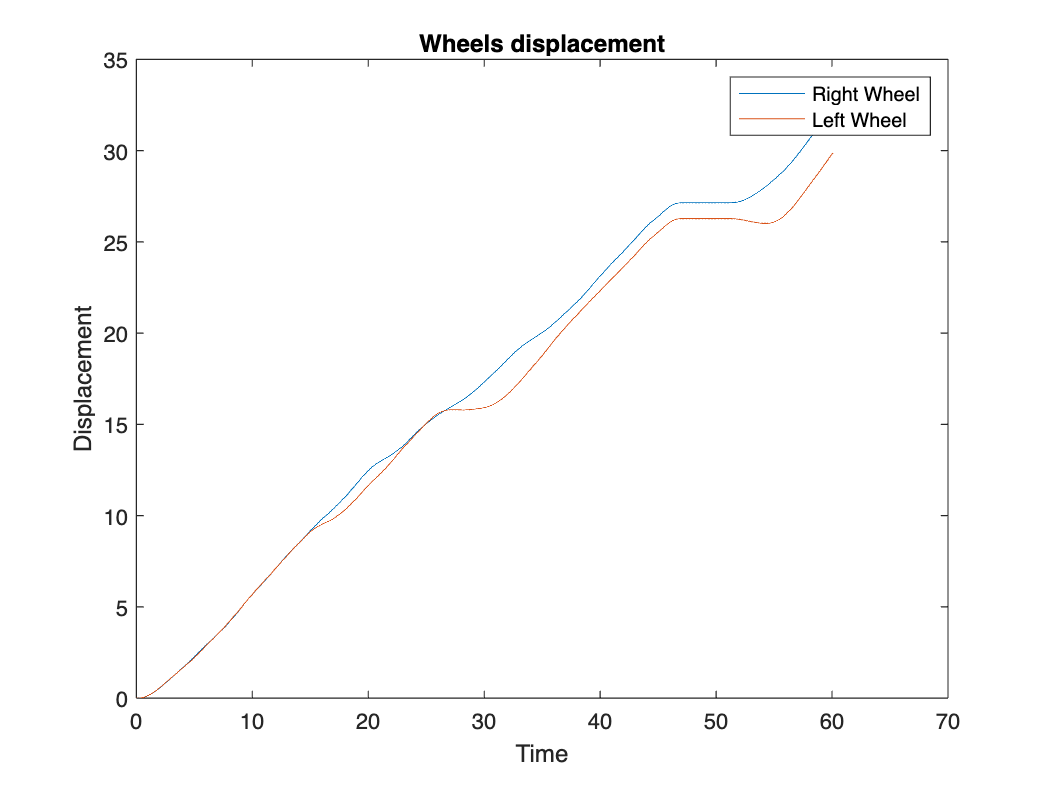

plot(R_acu(:,1),R_acu(:,2))
hold on
plot(L_acu(:,1),L_acu(:,2))

title('Wheels displacement')
ylabel('Displacement')
xlabel('Time')
legend('Right Wheel', 'Left Wheel');
L_inc = diff(L_acu(:,2));
R_inc = diff(R_acu(:,2));
hold off

## Visualize increment displacement

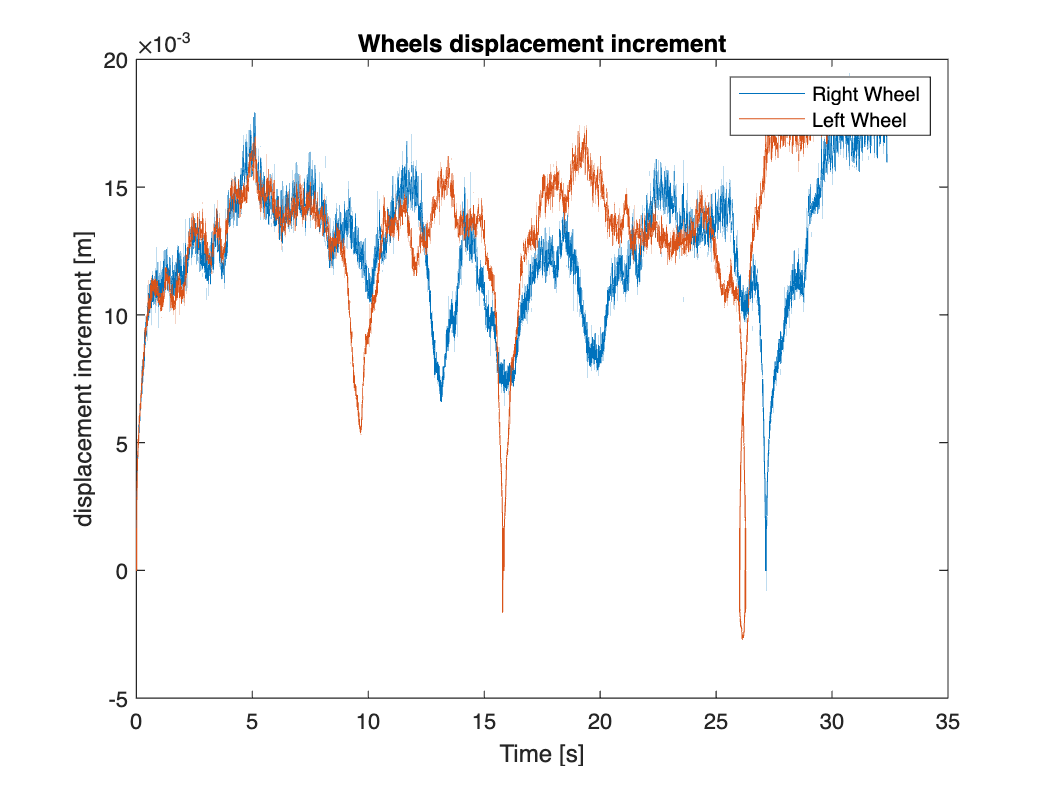

plot(R_acu(2:3004,2),R_inc(:))
hold on
plot(L_acu(2:3004,2), L_inc(:))

title('Wheels displacement increment')
ylabel('displacement increment [m]')
xlabel('Time [s]')
legend('Right Wheel', 'Left Wheel');
hold off

## Visualize increment velocity

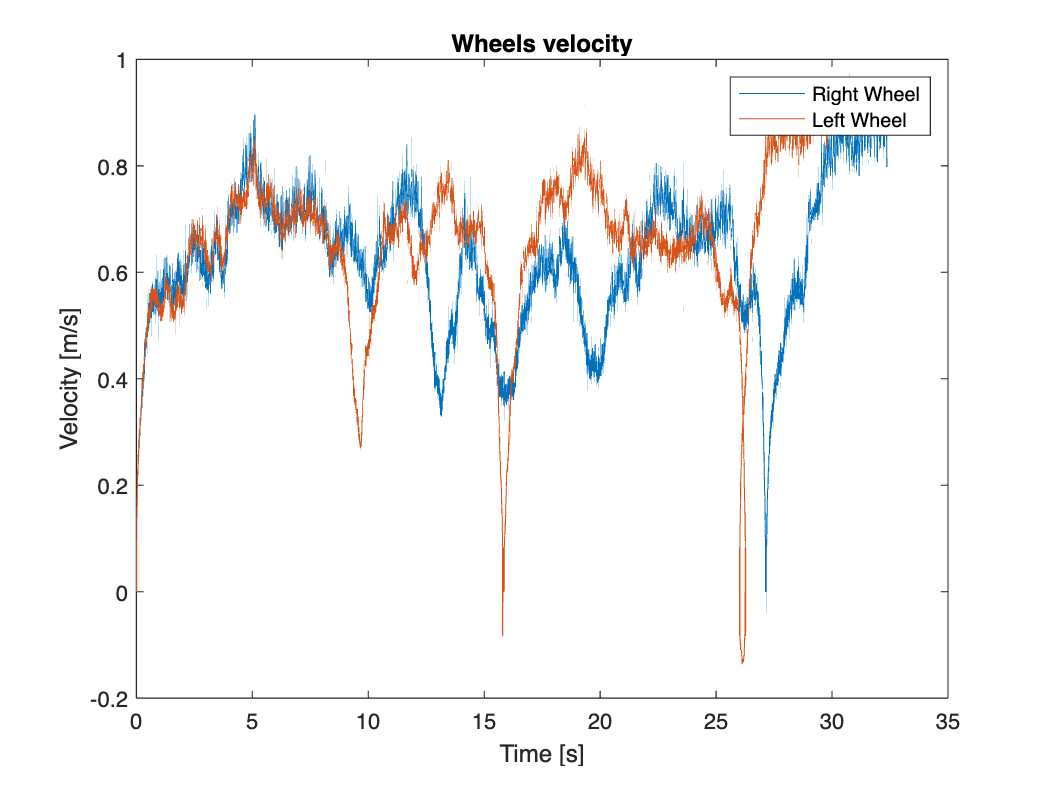

plot(R_acu(2:3004,2),R_inc(:)/Ts)
hold on
plot(L_acu(2:3004,2), L_inc(:)/Ts)

title('Wheels velocity')
ylabel('Velocity [m/s]')
xlabel('Time [s]')
legend('Right Wheel', 'Left Wheel');
hold off

clf % delete previous plots so we can hold on later and they don't all show up

## Odometry

Compute $\delta_x$ and $\delta_{\psi }$

delta_x= (R_inc+L_inc)/2;
delta_psi= (R_inc-L_inc)/(W);

## Pose integration

Compare your results

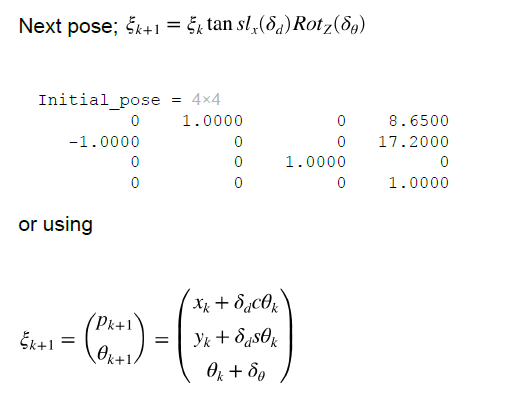

Initial_pose = transl(8.65,17.2,0)*trotz(-pi/2)

Initial_pose =          0    1.0000         0    8.6500
   -1.0000         0         0   17.2000
         0         0    1.0000         0
         0         0         0    1.0000


time = R_acu(:,1);
Initial_position=transl(Initial_pose);
% Preallocate for speed
x = zeros(1,length(time)-1);
y = zeros(1,length(time)-1);
o = zeros(1,length(time)-1);

x(1)=Initial_position(1);
y(1)= Initial_position(2);
o(1)= -pi/2;

for i = 1:length(time)-1
    x(i+1) = x(i) + delta_x(i)*cos(o(i));
    y(i+1) = y(i) + delta_x(i)*sin(o(i));
    o(i+1) = mod(o(i) + delta_psi(i),pi*2);
end

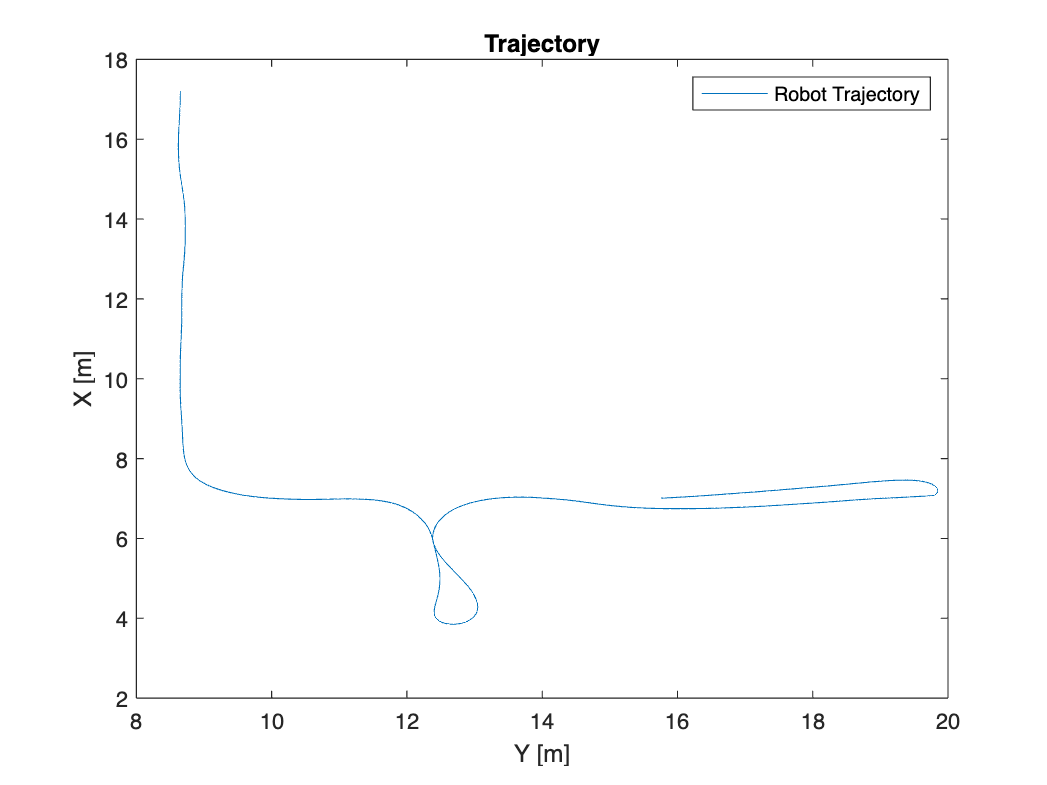

plot(x,y)

title('Trajectory')
ylabel('X [m]')
xlabel('Y [m]')
legend('Robot Trajectory');
hold on

## Adding noise

Add noise to odometry

See the effect on the trajectory

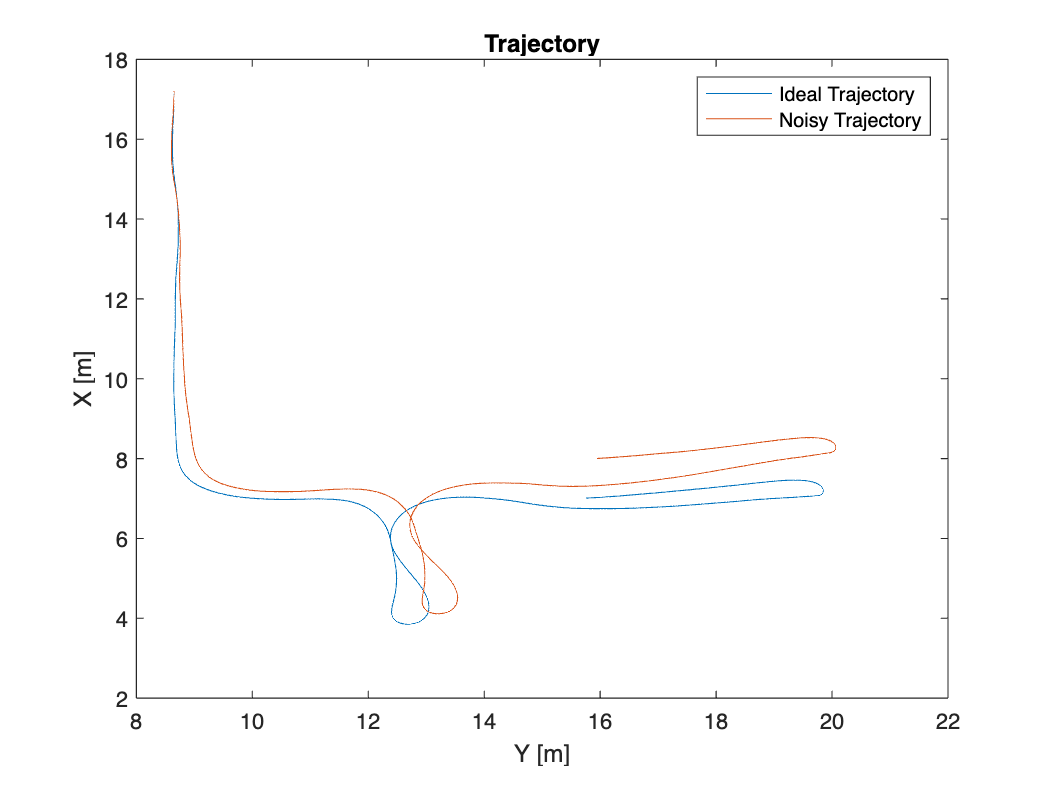

% Add gaussian noise
noise_std = 0.002; % adjust as needed
delta_x_noisy = delta_x + noise_std * randn(size(delta_x));
delta_psi_noisy = delta_psi + noise_std * randn(size(delta_psi));

x_noisy = zeros(1,length(time)-1);
y_noisy = zeros(1,length(time)-1);
o_noisy = zeros(1,length(time)-1);

x_noisy(1) = Initial_position(1);
y_noisy(1) = Initial_position(2);
o_noisy(1) = -pi/2;

for i = 1:length(time)-1
    x_noisy(i+1) = x_noisy(i) + delta_x_noisy(i)*cos(o_noisy(i));
    y_noisy(i+1) = y_noisy(i) + delta_x_noisy(i)*sin(o_noisy(i));
    o_noisy(i+1) = mod(o_noisy(i) + delta_psi_noisy(i),pi*2);
end

plot(x_noisy,y_noisy)

title('Trajectory')
ylabel('X [m]')
xlabel('Y [m]')
legend({'Ideal Trajectory', 'Noisy Trajectory'});

### Odometry displacement and orientation visualization with noise

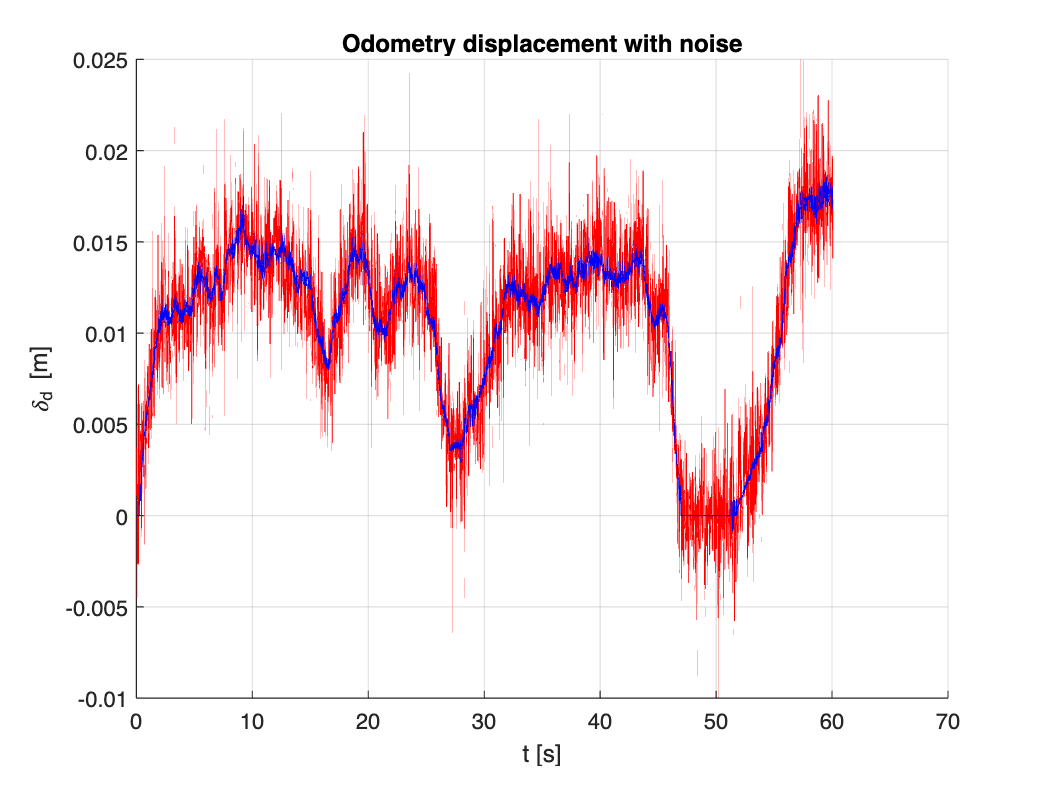

figure
hold on
grid on

plot(time(2:end),delta_x_noisy,'r')
title('Odometry displacement with noise')
xlabel('t [s]')
ylabel('\delta_d [m]')
plot(time(2:end),delta_x,'b')

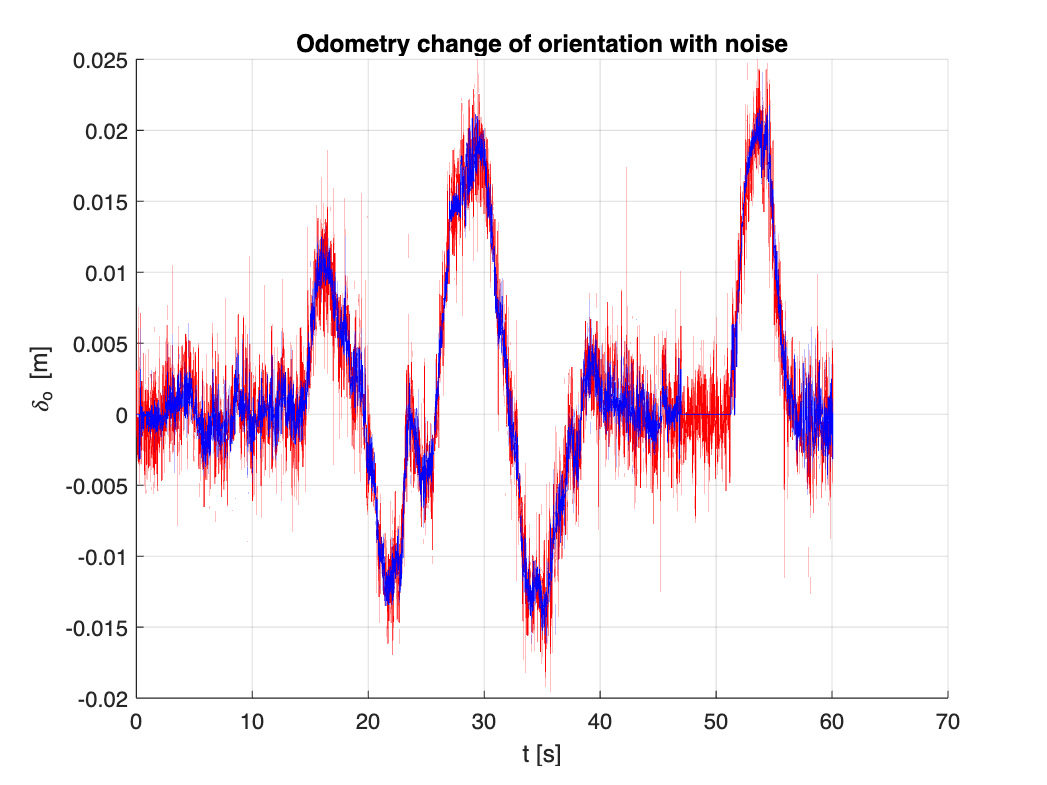

figure
hold on
grid on

plot(time(2:end),delta_psi_noisy,'r')
title('Odometry change of orientation with noise')
xlabel('t [s]')
ylabel('\delta_o [m]')
plot(time(2:end),delta_psi,'b')